# 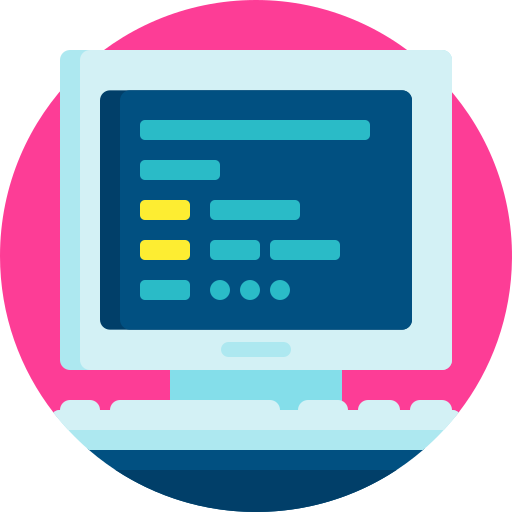

# Virtual Lab 3: Torsional mass-spring damper system

**This Virtual Lab covers content in Chapter 4-5 of the course notes**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## Mechanical systems with gears

Consider the system below:

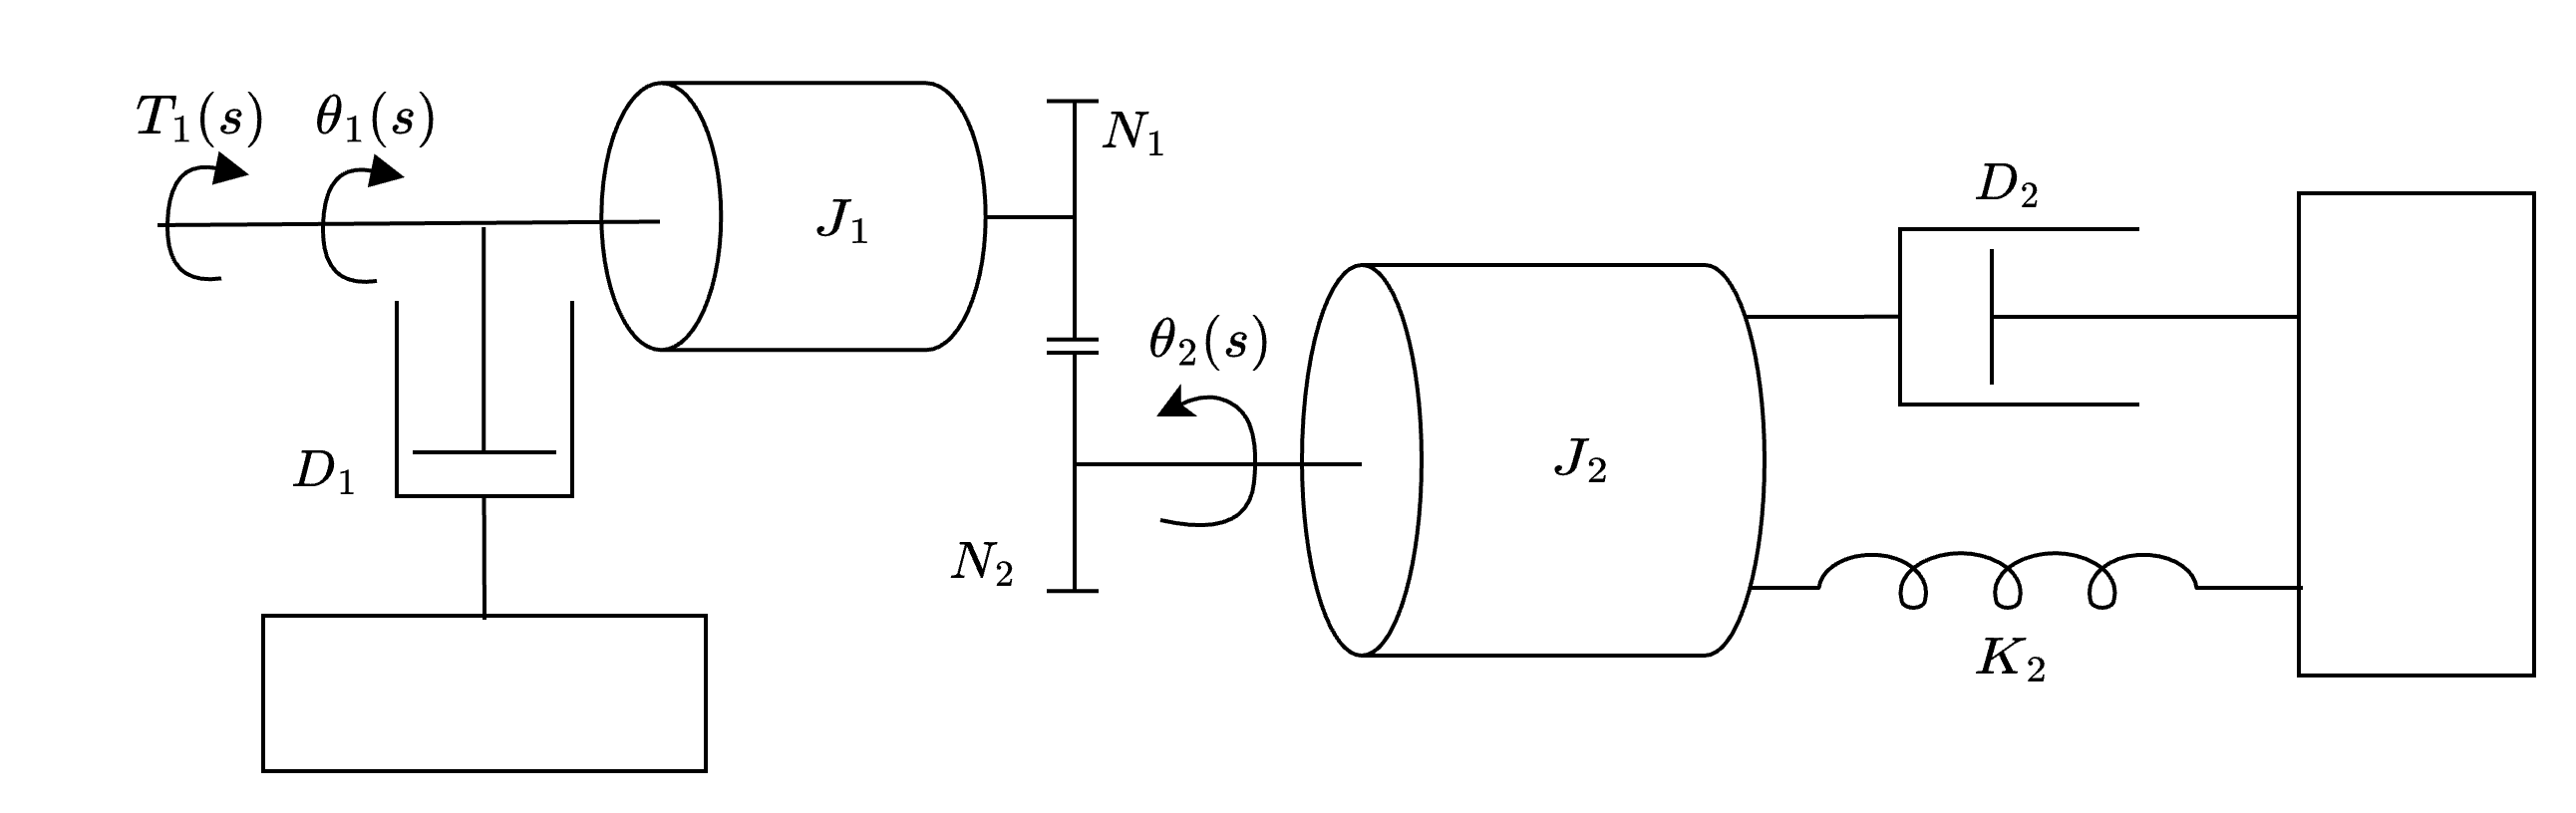

We are interested in finding the transfer function behaviour from $T_1(s)$ to $\theta_2(s)$.

#### **  Question 1: Upload an image of the equivalent system at the output shaft. You can leave the various parameters in their compact form, e.g. **$J_e,~D_e,~K_e$ (you do not need to have calculated them yet).

#### **  Question 2: Determine **$J_e$.

#### **  Question 3: Determine **$K_e$.

#### **  Question 4: Determine **$D_e$.

#### **  Question 5: Determine **$\frac{\theta_2(s)}{T_1(s)}$.

## Poles and zeros

As shown in **Chapter 2**, any arbitrary transfer function, $P(s)$, can be written as a ratio of polynomials

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}=\frac{N(s)}{D(s)}$,

where $\{a_i,b_i\}\in \mathbb{R}$ (the coefficients are real numbers) and $n\geq m$ (the denominator polynomial has equivalent or higher order than the numerator polynomial). Using factorization, $P(s)$ can be rewritten as a ratio of irreducible polynomials


$$\begin{array}{ll}
P(s) &= A \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}, \\
&= A\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)},
\end{array}$$


where 

- the $z_i$ terms are the roots of the equation $N(s)=0$ (setting the numerator polynomial to zero), and 

- the $p_i$ terms are the roots of the equation $D(s)=0$ (setting the denominator polynomial to zero). 

Note that $z_i$ and $p_i$ are complex numbers in general: $\{z_i,p_i\}\in\mathbb{C}$. Importantly, a real number is a special type of complex number, just with the imaginary component set to zero ( e.g. $z_i=3=3+j0$). We can also think of $z_i$ as a value of $s$ that makes $P(s)=0$, namely 

$P(z_i)=0$.

Similarly, $p_i$ is a value of $s$ that makes $P(s)$ tend to infinity, namely

$P(p_i)=\infty$.

Importantly, this definition assumes that $z_i \neq p_k,~\forall i,k$. In other words, simplification of the factors above is not possible, hence the term *ratio of irreducible polynomials*. 

We will refer to the $z_i$ terms as the **zeros** of $P(s)$, and the $p_i$ terms as the **poles **of $P(s)$*. *As we will see later in Chapter 5, the poles and zeros of our system actually tells us a lot of important information that we can use to determine performance and stability of our system. Note that the order (or degree) of the numerator polynomial, $N(s)$, is equal to the number of zeros of $P(s)$, and the order (or degree) of the denominator polynomial, $D(s)$, is equal to the number of poles of $P(s)$.

For example, given $P(s)=\frac{5s^2+15s+10}{s^3+8s^2+15s}=\frac{5(s+1)(s+2)}{s(s+3)(s+5)}$, the poles and zeros follow as

**zeros: **$(z_1,z_2)=(-1,-2)$

**poles: **$(p_1,p_2,p_3)=(0,-3,-5)$

We can confirm the result above using `MATLAB:`

%example
s = tf('s');    %define the Laplace variable using the tf library
P = (5*s^2+15*s+10)/(s^3+8*s^2+15*s)    %define P(s)
P = zpk(P)  %represent P(s) in zero-pole-gain form (factorising numerator and denominator). Not required, but nice for visualisation

[poles,zeros] = pzmap(P) %find poles and zeros of P(s)


### Pole-zero plot (s-plane)

The pole and zero locations in the complex plane infer a variety of characteristics of the system, such as rate of exponential growth/decay, frequency of oscillation, and stability (more on this later). We can explicitly define the $i^{th}$ **pole** of $P(s)$ as

$p_i=a_i+jb_i$,

where $a_i=\mathcal{R}\{p_i\}$ is the real component of pole $i$ and $b_i=\mathcal{I}\{p_i\}$ is the corresponding imaginary component. We can similarly define the $k^{th}$ **zero **of $P(s)$ as

$z_k=c_k+jd_k$.

Each pole and zero of $P(s)$ can be visualised on the complex plane, hereafter referred to as the **s-plane**, where poles are indicated with a $\times$ symbol, and zeros are shown with a $\bigcirc$ symbol, as seen below.

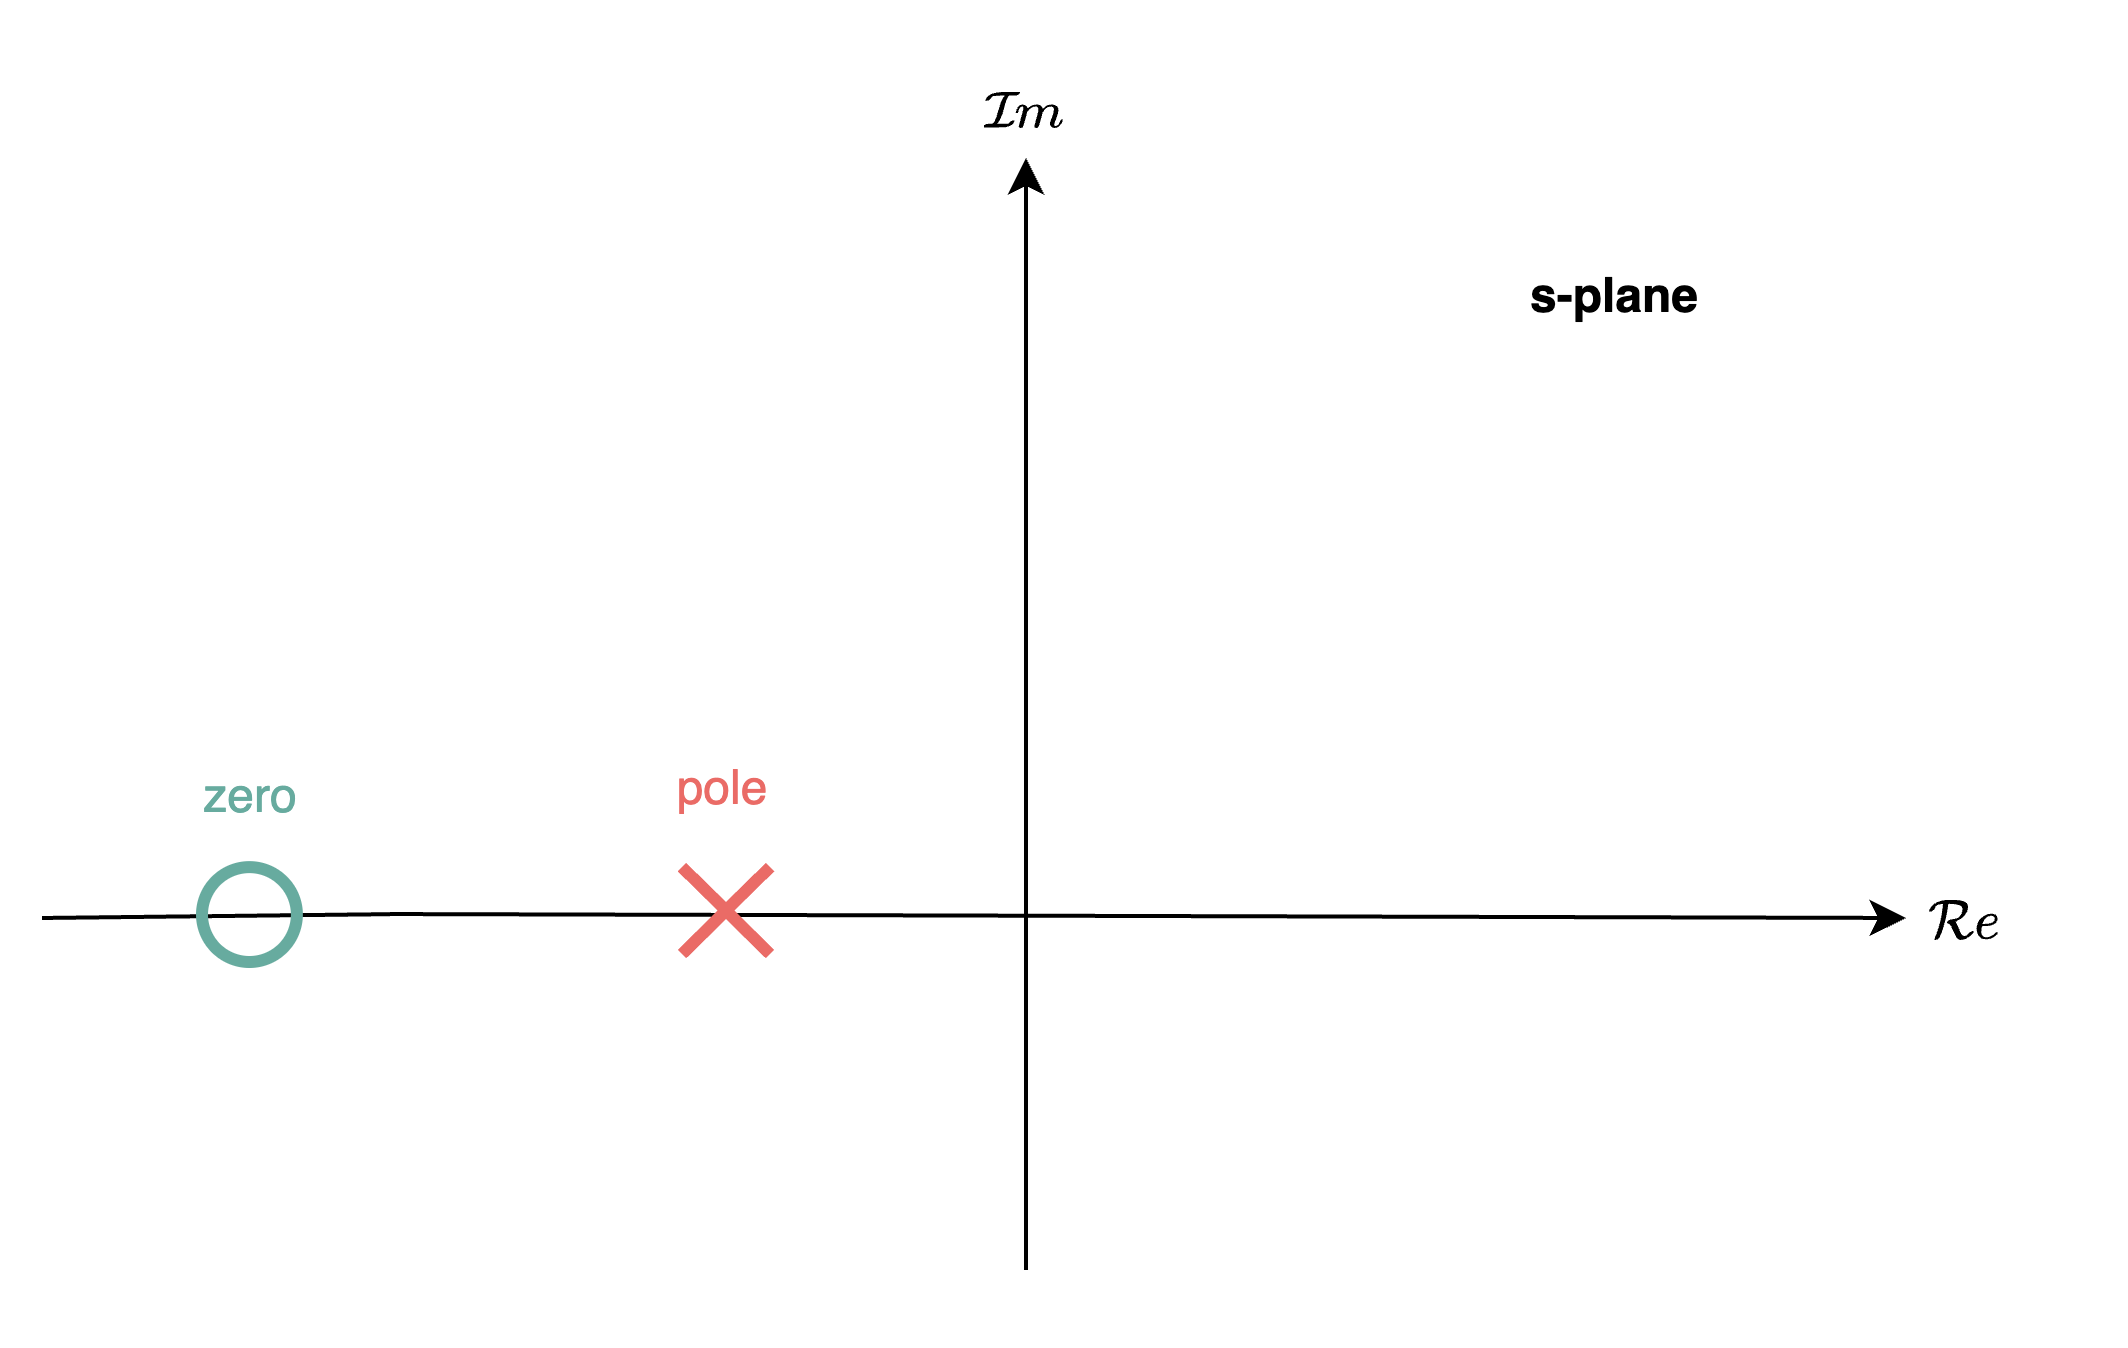

Recall that the $x$-axis of the complex plane indicates the *real* component of a complex number, and the $y$-axis indicates the *imaginary* component. The `MATLAB` function `pzmap` takes a transfer function as input and displays the pole-zero locations in the s-plane. We can use this to visualise the poles and zero of our torsional mass-spring-damper system if we assign numerical parameters to the mechanical coefficients.

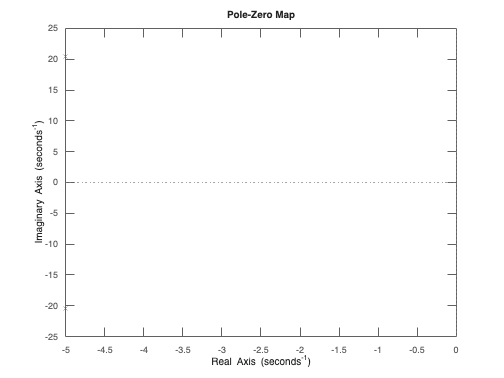

s = tf('s');

N1 = 1; %number of teeth of input gear
N2 = 1; %number of teeth of output gear
Ke = 22; %equivalent spring constant
De = 0.5; %equivalent damping ratio
Je = 0.05; %equivalent inertia
P = ( N2/N1 )/(Ke+De*s+Je*s^2);

figure,hold on
pzmap( P )

[poles,zeros] = pzmap( P )

poles =   -5.0000 +20.3715i
  -5.0000 -20.3715i



zeros =

  0×1 empty double column vector



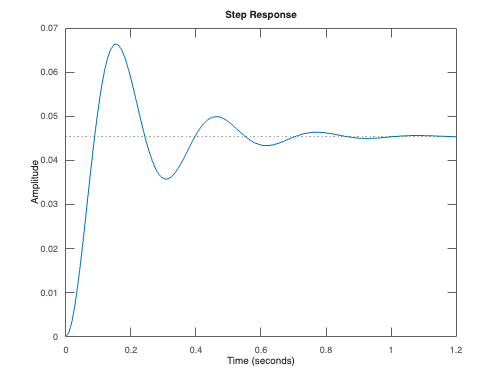

figure
step(P)

Firstly, it should be clear that our system has no zeros. Playing around with the numerical sliders, we should see that our poles will move around in the s-plane and this will also affect the output response behaviour. Additionally, the poles can either be real-valued, or complex, depending on the particular combination of mechanical parameters. The gear ratio, $N_2/N_1$, can be seen to scale to the output response, but it has no effect on the location of the poles. There is also a relationship between the location of the poles in the s-plane and the corresponding step response (although the relationship is not currently obvious).

Visualising the effect of the mechanical parameters has some use, but we can get a better understanding of the system by determining the algebraic poles of the system as a function of the mechanical parameters.

####  Question 6: Determine the poles of $P(s)=\frac{N_2/N_1}{K_e+D_es+J_es^2}$ by hand.

*Hint: use MATLAB to confirm your answer.*

%code block (if required)


Assuming you correctly calculated the algebraic poles of our torsional mass-spring-damper system, it should now be clear why the poles of our system can be either strictly real, or complex. 

####  Question 7: Under what condition will the poles of $P(s)$ be strictly real (no imaginary components)?

*Hint: use the simulation code above to confirm your answer.*

## Step response with real-valued poles

You may have already noticed, but depending on when the poles of our system are strictly real or complex, the output response exhibits a different type of response. Consider the case when the poles of our system are real and distinct. That is, the two poles have no imaginary components are not equivalent to each other. An example is given below, with the pole-zero map and step response also shown.

s = tf('s');

N1 = 2; %number of teeth of input gear
N2 = 1; %number of teeth of output gear
Ke = 4; %equivalent spring constant
De = 5; %equivalent damping ratio
Je = .8; %equivalent inertia

P = ( N2/N1 )/(Ke+De*s+Je*s^2);

figure,hold on
pzmap( P )

figure
step(P)

To get a better understanding of why our response looks like this, we can make use of partial faction decomposition of $Y(s)=P(s)U(s)$, where $U(s)$ is a unit step input.

Recall that a strictly proper plant with real, distinct poles can be described as


$$\begin{array}{ll}
P(s) &=  A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i},
\end{array}$$


where 

$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)$.

By extension, the step response of $P(s)$, namely $Y(s)=P(s)\frac{1}{s}$, can be expanded using


$$\begin{array}{ll}
Y(s) 
&= P(s)\frac{1}{s},\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i}+\frac{r_{n+1}}{s},
\end{array}$$


where 

$r_i = \lim_{s\rightarrow p_i} (s-p_i)Y(s)$.

Refer to the **Chapter 5** notes if you need a more detailed refresher. This means that we can express the step response of our torsional mass-spring-damper system as 


$$\begin{array}{ll}
Y(s)
&= \frac{N_2/N_1}{J_es^2+D_es+K_e}\frac{1}{s},\\
&= \frac{N_2/(N_1J_e)}{s^2+(D_e/J_e)s+K_e/J_e}\frac{1}{s},\\
&= \frac{r_1}{s-p_1}+\frac{r_2}{s-p_2}+\frac{r_3}{s},
\end{array}$$


where $p_1,p_2$ are the poles of our system using the numerical values defined in the code block above.

####  Question 8: Determine $p_1$, $p_2$, $r_1$, $r_2$, and $r_3$ by hand, where $p_1<p_2$. Provide your answer to three decimal places and show all working.

*Hint: you can confirm your answers for Question 8 by resolving the three terms of *$Y(s)$ into a single term to see if it matches the polynomial ratio form of $Y(s)$.

%Code block (if required)


Once we have determined $Y(s)$ as a function of first-order terms, we can then find $y(t)$ by simply taking the inverse Laplace transform of each term and then summing the result, namely


$$\begin{array}{ll}
y(t) 
&= \mathcal{L}^{-1}\{\frac{r_1}{s-p_1}\}+\mathcal{L}^{-1}\{\frac{r_2}{s-p_2}\}+\mathcal{L}^{-1}\{\frac{r_{3}}{s}\},\\
&=   {r_1}e^{a_1t}+{r_2}e^{a_2t}+r_{3},
\end{array}$$


where $p_i=a_i+j0$. The step response is therefore made up of two exponentially decaying functions (the first two terms above), and a constant value as a result of the step input (the third term above). Given that $\{a_1,a_2\}<0$, we can expect that the output response will tend to $r_3$ as time tends to infinity: 

$\lim_{t\rightarrow\infty}y(t)=r_3$.

Based on this result, we could have actually determined $r_3$ by looking at the steady-state value of the step response.

The magnitude of $a_1$ and $a_2$ will also affect the rate at which each exponential decays, and by extension, how quickly $y(t)$ tends to $r_3$. We can confirm that the expansion of $y(t)$ above matches that of our initial step response using `MATLAB`'s `step` function using the code block below.

####   **Task:** Fill in your numerical parameters from Question 8 and run the code block. 

s = tf('s');

N1 = 2; %number of teeth of input gear
N2 = 1; %number of teeth of output gear
Ke = 4; %equivalent spring constant
De = 5; %equivalent damping ratio
Je = .8; %equivalent inertia

P = ( N2/N1 )/(Ke+De*s+Je*s^2); %P(s)
[y,t] = step(P); %step response data

%Fill in the following parameters: r1,r2,r3,p1,p2
r1 = NaN;
r2 = NaN;
r3 = NaN;
p1 = NaN;
p2 = NaN;

y_ = r1*exp(p1*t)+r2*exp(p2*t)+r3; %sum of individual responses, which should be equivalent to the step response

figure, hold on
plot(t,y,'b',lineWidth=2)
plot(t,y_,'r--',lineWidth=2)

*Hint: if the two graphs are not matching, your residual or pole values are incorrect. Note that ordering is also important in that the residual and pole values are matched!*

## Step response with complex-valued poles

The previous section considered the scenario when the mechanical parameters of our system result in real-valued poles, which gave rise to a step response that was made up of decaying exponentials and a constant term. We will now consider when the mechanical parameters result in complex poles. The code block below contains parameters that result in complex conjugate poles ($p_1=p_2^*$).

s = tf('s');

N1 = 2; %number of teeth of input gear
N2 = 1; %number of teeth of output gear
Ke = 4; %equivalent spring constant
De = 1; %equivalent damping ratio
Je = .8; %equivalent inertia

P = ( N2/N1 )/(Ke+De*s+Je*s^2);

figure,hold on
pzmap( P )

figure
step(P)

The step response shown now exhibits an oscillatory behaviour, where the response also overshoots the steady-state value initially. This oscillatory response was not present when we had strictly real-valued poles and is worth investigating! When $U(s)$ is a unit step input, the output response, $Y(s)=P(s)\frac{1}{s}$, can be decomposed as before using


$$\begin{array}{ll}
Y(s)
&= \frac{N_2/N_1}{J_es^2+D_es+K_e}\frac{1}{s},\\
&= \frac{r_1}{s-p_1}+\frac{r_2}{s-p_2}+\frac{r_3}{s}.
\end{array}$$


However, $p_1$ and $p_2$, and by extension, $r_1$ and $r_2$, will now be complex numbers. We can determine $r_i$ as before using

$r_i = \lim_{s\rightarrow p_i} (s-p_i)Y(s)$.

####  Question 9: Determine $p_1$,$p_2$, $r_1$, $r_2$, and $r_3$. Provide your answer to four decimal places and show all working.

*Hint: you can confirm your answers for Question 11 and 12 by resolving the three terms of *$Y(s)$ into a single term to see if it matches the polynomial ratio form of $Y(s)$.

%Code block (if required)


Once we have determined $r_i$ and $p_i$, we can determine $y(t)$ using the inverse Laplace transform:


$$\begin{array}{ll}
y(t) 
&= \mathcal{L}^{-1}\{\frac{r_1}{s-p_1}\}+\mathcal{L}^{-1}\{\frac{r_2}{s-p_2}\}+\mathcal{L}^{-1}\{\frac{r_{3}}{s}\},\\
&=   {r_1}e^{p_1t}+{r_2}e^{p_2t}+r_{3},
\end{array}$$
 

However, $p_1$ and $p_2$ are now complex numbers, so we are not just dealing with real-valued exponentials as before. It can be shown (in the **Chapter 5** course notes) that the above equation can be reduced to


$$y(t)=2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi)+ r_3,
$$


where $p_i=a_i+jb_i$, $r_1=v_1+w_1$, and $\phi=-\tan^{-1} \frac{w_1}{v_1}}$ (strictly speaking, we should use `atan2` when calculating $\phi$).  The oscillatory response arising from the complex conjugate poles can therefore be understood based on the fact that $y(t)$ is made up of a co-sinusoid with exponential decay and a constant term. The function $2\sqrt{v_1^2+w_1^2}e^{a_1t}$ represents the amplitude of the cosine function and will shrink over time if $a_i<0$. Under these conditions, we still expect

$\lim_{t\rightarrow\infty}y(t)=r_3$,

which means that we can also determine $r_3$ by checking the steady-state value that the output response tends to when simulating the step response. We now have some understanding between the type of poles in the system, and the resulting response. We will cover this in more detail over the next two weeks.

Reflecting on the equation of $y(t)$ above, if $a_1=0$, implying that the poles of our system are purely imaginary, then the output response will continue to oscillate for all time, namely


$$\begin{array}{rl}
y(t)
&=2\sqrt{v_1^2+w_1^2}e^{0t}\cos(b_1t-\phi)+ r_3,\\
&=2\sqrt{v_1^2+w_1^2}\cos(b_1t-\phi)+ r_3.
\end{array}
$$


####  Question 10: Given that $\{J_e,K_e\}>0$, under what condition will the poles of $P(s)$ be purely imaginary?

An example of such a response can be generated using the code below.

s = tf('s');

N1 = 2; %number of teeth of input gear
N2 = 1; %number of teeth of output gear
Ke = 4; %equivalent spring constant
De = 0; %equivalent damping ratio
Je = .8; %equivalent inertia

P = ( N2/N1 )/(Ke+De*s+Je*s^2);

figure,hold on
pzmap( P )
[poles,zeros] = pzmap( P )

figure
step(P,20) %simulate step response for 20 seconds

#### **  Question 11: Rename your completed live script to include your student number (e.g. VirtualLab3_SMTJOH999.mlx) and submit it as your answer.**

***This concludes Virtual Lab 2. ***